# **Distributed-parameter transducer model for the stepped-plate parametric array loudspeaker**

**2023-01-03 ~**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

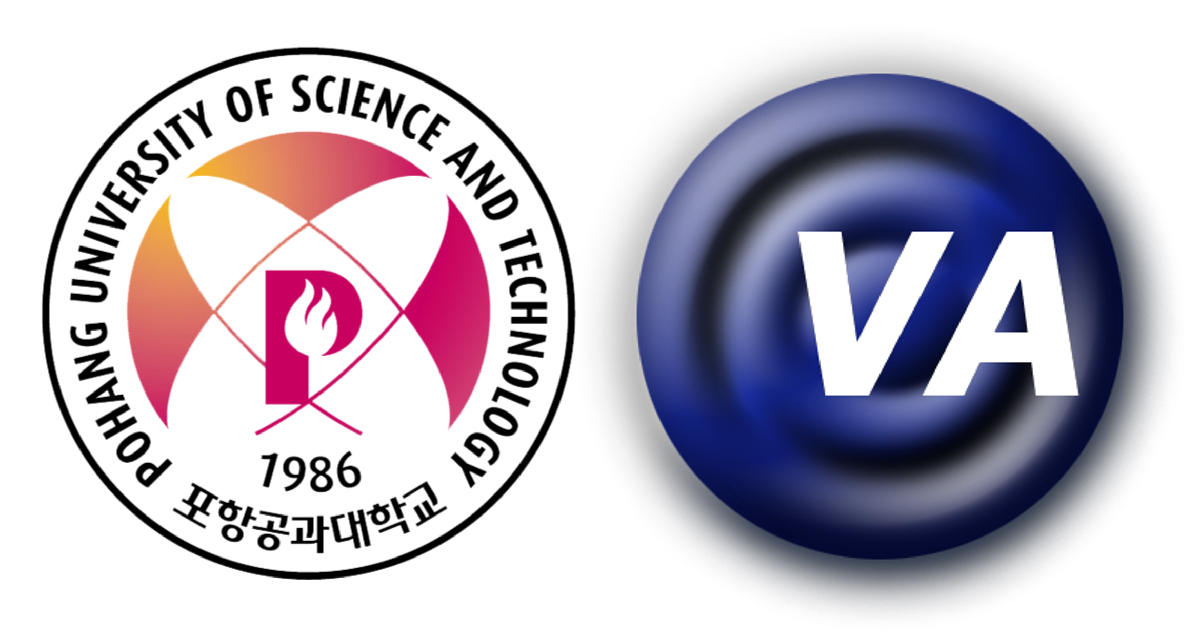

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

clear

% Define the structure
n_start = 1;    % Start index of node;
n_end   = 5;    % End index of node;
if n_start > n_end
    disp("Error: the end index of node must be greater than start index!");
    return
end
e_no    = n_end - n_start;
n_no    = e_no+1;
S = sprintf("The number of elements:    %d\n" + ...
    "The number of nodes:       %d",e_no,n_no);
disp(S);

The number of elements:    4
The number of nodes:       5



% Initialize the symbols for material properties and design parameters of
% elements
rho = sym('rho_%d', [1 n_end]);
c   = sym('c_%d', [1 n_end]);
k   = sym('k_%d', [1 n_end]);
l   = sym('l_%d', [1 n_end]);
A   = sym('A_%d', [1 n_end]);


The effort and flow variable vectors are $F=
\left[
\matrix{
F_1\cr
F_2\cr
F_3\cr
\vdots \cr
F_{-2}\cr
F_{-1}\cr
F_0\cr
}
\right]$ and $u=
\left[
\matrix{
u_1\cr
u_2\cr
u_3\cr
\vdots \cr
u_{-2}\cr
u_{-1}\cr
u_0\cr
}
\right]$ where 1 and 0 are the node's start and end indices, and the minus sign is the reversed order from the end index.

% Initialize the symbols for effort and flow variable vectors
F   = sym('F_%d',[1 n_end]).';
u   = sym('u_%d',[1 n_end]).';
F(1:n_start-1)  = [];
u(1:n_start-1)  = [];


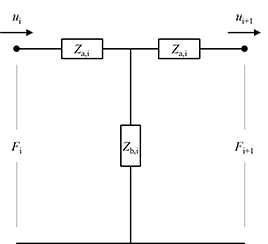

**Figure 1** The symmetric T-network for a bar where $Z_{\rm{a,i}}=j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \tan{\frac{k_{\rm{i}} l_{\rm{i}}}{2}}$, $Z_{\rm{b,i}}=-\frac{j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}}}{\sin{k_{\rm{i}} l_{\rm{i}}}}$

% Calculating the bar's impedance for symmetric T-network
Z_b = sym('Z_b_%d',[1 n_end]);  % Z_b
Z_c = sym('Z_c_%d',[1 n_end]);  % Z_c = Z_a + Z_b
Z_d = sym('Z_d_%d',[1 n_end]);  % Z_d for the boundary conditions of both ends

for i=n_start:n_end
    Z_b(i) = -1j*rho(i)*c(i)*A(i)/(sin(k(i)*l(i)));
    Z_c(i) = -1j*rho(i)*c(i)*A(i)*cot(k(i)*l(i));
end

rho(1:n_start-1)    = [];
c(1:n_start-1)      = [];
k(1:n_start-1)      = [];
l(1:n_start-1)      = [];
A(1:n_start-1)      = [];


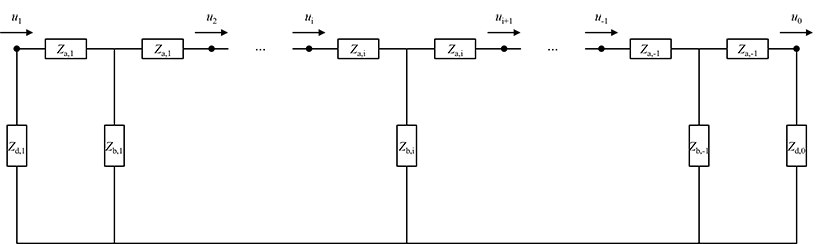

**Figure 2** The symmetric T-network for bars mechanically connected in series and its boundary conditions of both ends

The impedance matrix is $Z=
\left[
\matrix{
Z_{\rm{c,1}}+Z_{\rm{d,1}}  & -Z_{\rm{b,1}} & 0 & \cdots & 0 & 0 & 0 \cr
-Z_{\rm{b,1}} & Z_{\rm{c,1}}+Z_{\rm{c,2}} & -Z_{\rm{b,2}} &  \cdots & 0 & 0 & 0 \cr
0 & -Z_{\rm{b,2}} & Z_{\rm{c,2}}+Z_{\rm{c,3}} & \cdots & 0 & 0 & 0 \cr
\vdots & \vdots & \vdots & \ddots & \vdots & \vdots & \vdots \cr
0 & 0 & 0 & \cdots & Z_{\rm{c,-3}}+Z_{\rm{c,-2}} & -Z_{\rm{b,-2}} & 0 \cr
0 & 0 & 0 & \cdots & -Z_{\rm{b,-2}} & Z_{\rm{c,-2}}+Z_{\rm{c,-1}} & -Z_{\rm{b,-1}} \cr
0 & 0 & 0 & \cdots & 0 & -Z_{\rm{b,-1}} & Z_{\rm{c,0}}+Z_{\rm{d,0}} \cr
}
\right]$ where $Z_{\rm{a,i}}=j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \tan{\frac{k_{\rm{i}} l_{\rm{i}}}{2}}$, $Z_{\rm{b,i}}=-\frac{j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}}}{\sin{k_{\rm{i}} l_{\rm{i}}}}$, $Z_{\rm{c,i}}=Z_{\rm{a,i}}+Z_{\rm{b,i}}=-j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \cot{k_{\rm{i}} l_{\rm{i}}}$.

% Constructing the impedance matrix
Z = sym('Z_%d_%d',[n_end n_end]);

Z(n_start,n_start)          = Z_c(n_start) + Z_d(n_start);
Z(n_start,n_start+1)        = -Z_b(n_start+1);
Z(n_start,n_start+2:n_end)  = 0;

for i=n_start+1:n_end-1
    Z(i,n_start:i-2)  = 0;
    Z(i,i-1)    = -Z_b(i-1);
    Z(i,i)      = sum(Z_c(i:i+1));
    Z(i,i+1)    = -Z_b(i);
    Z(i,i+2:n_end)= 0;
end

Z(n_end, n_start:n_end-2) = 0;
Z(n_end, n_end-1)   = -Z_b(n_end-1);
Z(n_end, n_end)     = Z_c(n_end) + Z_d(n_end);

Z(1:n_start-1,:)    = [];
Z(:,1:n_start-1)    = [];
